# Bode Diagrams approximation

#### group: 30332 halfgroup 2

#### student: Pacuraru Fabian-Virgil

#### Request: 

#### Write a matlab script in order to approximate Bode Diagrams by asymptotes (no matter the structure of the transfer function).

In order to evaluate the efficiency of our code, we are going to test it on 5 different transfer functions:


$$H_1 \left(s\right)=30\frac{s\left(s+5\right)}{\left(2s+3\right)\left(s+12\right)}=\frac{30s^2 +150s}{2s^2 +27s+36}$$


H(1) = tf([30 150 0],[2 27 36]);


$$H_2 \left(s\right)=600\frac{4s+100}{\left(s+300\right)\left(s+700\right)}=\frac{2400s+60000}{s^2 +1000s+210000}$$


H(2) = tf([2400 60000],[1 1000 210000]);


$$H_3 \left(s\right)=\frac{2s^2 }{s^2 +50s+2500}$$


H(3) = tf(2,[1 50 2500]);


$$H_4 \left(s\right)=\frac{0\ldotp 1\left(s^2 +20s+400\right)}{s^2 +s+400}$$


H(4) = tf(0.1*[1 20 400],[1 1 400]);


$$H_5 \left(s\right)=\frac{0\ldotp 25}{s\left(25s^2 +s+1\right)}=\frac{0\ldotp 25}{25s^3 +s^2 +s}$$


H(5) = tf(0.25,[25 1 1 0]);

Now that we declared our functions, we are going to try to approximate their Bode Diagrams.

for c = 1:length(H)
    % we calculate the gain and the slopes 
    [K, initialSlope, slopes] = calculateGainAndSlopes(H(c));
    % we calculate the zeros and the poles of the transfer function
    [allZeros, allPoles] = calculateZerosAndPoles(H(c));
    % we take the mean of the roots, in order to better work with them
    % if the values for poles or zeros are complex numbers
    allZeros = sqrt(real(allZeros).^2+imag(allZeros).^2);
    allPoles = sqrt(real(allPoles).^2+imag(allPoles).^2);
    % we put all the roots into a single vector and we sort them
    % sorting the roots alongside the slopes will show us the evolution
    % of the magnitude and the phase as frequency increases
    [sortedRoots, slopes] = sortRootsAndSlopes(allZeros, allPoles, slopes);
    % we then calculate some important values of the frequency for plotting
    % the evolution of the magnitude
    wma = calculateMagnitudeFrequencies(sortedRoots);
    % we then calculate some important values of the frequency for plotting
    % the evolution of the phase
    wfa = calculatePhaseFrequencies(wma);


In order to represent our aproximations on the Bode Diagram, we need to calculate the values of our magnitude and phase for the already calculated important frequencies.

I implemented two methods for calculating each magnitude and phase.

#### The magnitude can be calculated using two functions implemented at the end of this document:

    % First method (function 'calculateMagnitudeValue1')
    ma1 = zeros(1,length(wma));
    for i = 1:length(wma)
        ma1(i) = calculateMagnitudeValue1(K, allZeros, allPoles, wma(i));
    end

    % Second method (function 'calculateMagnitudeValues2')
    ma2 = calculateMagnitudeValues2(K, wma, initialSlope, slopes);

#### The phase can be calculated  using two functions implemented at the end of this document:

    % First method (function 'calculatePhaseValue1')
    fa1 = zeros(1,length(wfa));
    for i = 1:length(wfa)
        fa1(i) = calculatePhaseValue1(K, allZeros, allPoles, wfa(i));
    end

    % Second method (function 'calculatePhaseValues2')
    fa2 = calculatePhaseValues2(wfa, initialSlope, slopes);

We then take our calculations and plot them alongside the bode diagram.

 
First Transfer Function

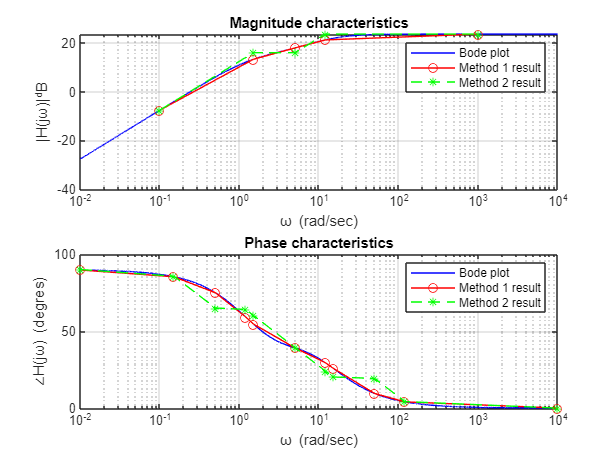

 
Second Transfer Function

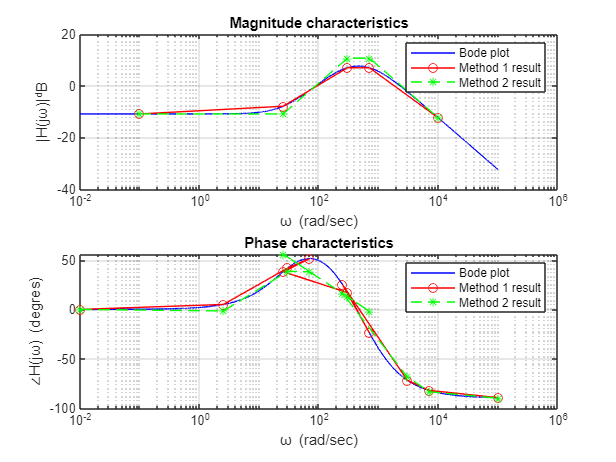

 
Third Transfer Function

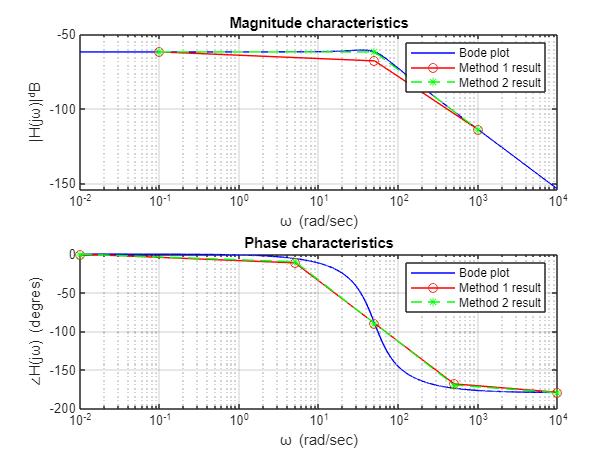

 
Fourth Transfer Function

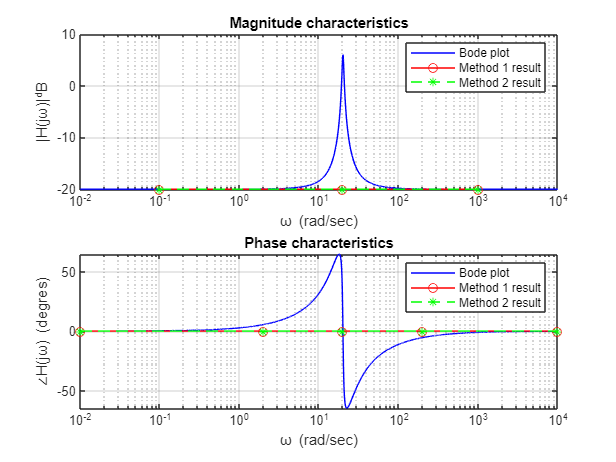

 
Fifth Transfer Function


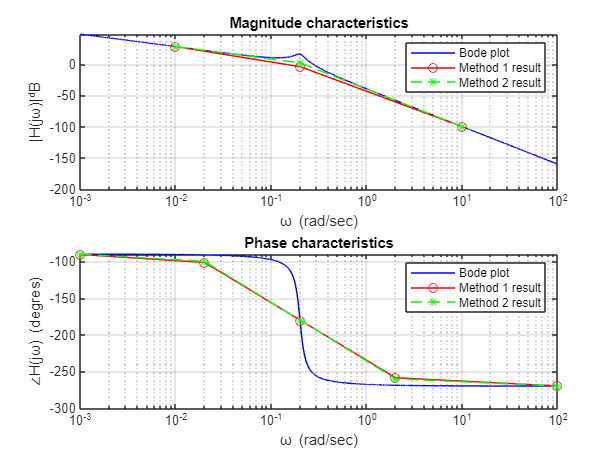

    if(c==1)
        % helps us know the next representation was made for the first tf
        fprintf(' \nFirst Transfer Function');
        figure('Name','First Transfer Function');
    end
    % the next 14 lines of code were taken from the lab because they plot
    % our results alongside the bode diagram, so we can easily compare them
    w=logspace(log10(wfa(1)),log10(wfa(end)),1e4);
    bode(H(c),w)
    [m,f]=bode(H(c), w);
    mv(1:1e4,1)=m(:,:,:);fv(1:1e4,1)=f(:,:,:);

    % magnitude
    subplot(211); semilogx(w,20*log10(mv),'b',wma,ma1,'ro-',wma,ma2,'g*--');
    grid; title('Magnitude characteristics');
    legend('Bode plot','Method 1 result','Method 2 result');
    xlabel('\omega (rad/sec)');
    ylabel('|H(j\omega)|^dB');

    % phase
    subplot(212); semilogx(w,fv,'b',wfa,fa1,'ro-',wfa,fa2,'g*--');
    grid; title('Phase characteristics');
    legend('Bode plot','Method 1 result','Method 2 result');
    xlabel('\omega (rad/sec)');
    ylabel('\angleH(j\omega) (degres)');
    
    % the next switch names the figures and also writes the number of the
    % transfer functions in order to know which diagram is done for which tf
    switch c
        case 1
            fprintf(' \nSecond Transfer Function');
            figure('Name','Second Transfer Function');
        case 2
            fprintf(' \nThird Transfer Function');
            figure('Name','Third Transfer Function');
        case 3
            fprintf(' \nFourth Transfer Function');
            figure('Name','Fourth Transfer Function');
        case 4
            fprintf(' \nFifth Transfer Function\n');
            figure('Name','Fifth Transfer Function');
    end
end

### The functions implemented to do the calculations:

% the function 'calculateGainAndSlopes' calculates the gain and the values
% that modify the initial slope after each important frequency

function [K, initialSlope, slopes] = calculateGainAndSlopes(H)
    % we take the coefficients of numerator and denominator
    % of the transfer function into different vectors
    [num,den] = tfdata(H);
    % we initialize the initial slope with 0
    initialSlope = 0;
    % in the next while we check the denominator for last 0 coefficients
    % in order to determine if the initial slope is 0 or not
    i = length(den{1});
    while(den{1}(i)==0)
        % we also cut the last 0 coefficients because they are already
        % taken into account on the initial slope
        den{1} = den{1}(1:(end-1));
        initialSlope = initialSlope - 20;
        i = i-1;
    end
    % in the next while we check the same thing as the previous while,
    % but for the numerator
    i = length(num{1});
    while(num{1}(i)==0)
        % we also cut the last 0 coefficients because they are already
        % taken into account on the initial slope
        num{1} = num{1}(1:(end-1));
        initialSlope = initialSlope + 20;
        i = i-1;
    end
    % we calculate the gain
    K = num{1}(end)/den{1}(end);
    % we calculate the non-zero roots of the numerator and denominator
    numRoots = roots(num{1});
    denRoots = roots(den{1});
    % we store all the modifications of the slope into 'slopes' vector
    slopes = zeros(1,length(numRoots)+length(denRoots));
    % after each root of the numerator, the slope increases by 20dB
    for i = 1:length(numRoots)
        slopes(i) = 20;
    end
    % after each root of the denominator, the slope decreases by 20dB
    for i = (length(numRoots)+1):(length(numRoots)+length(denRoots))
        slopes(i) = -20;
    end
end


% the function 'calculateZerosAndPoles' calculates all the roots of the
% numerator and denominator, even the non-zero ones
function [allZeros, allPoles] = calculateZerosAndPoles(H)
    % we take the coefficients of numerator and denominator
    % of the transfer function into different vectors
    [num,den] = tfdata(H);
    % we store the roots of the numerator in the vector 'allZeros'
    allZeros = (-1)*roots(num{1});
    % we store the roots of the denominator in the vector 'allPoles'
    allPoles = (-1)*roots(den{1});
end


% the function 'sortRootsandSlopes' sorts the values of all roots in
% increasing order while also modifying the 'slopes' vector in order to
% understand how does the magnitude evolve while the pulsation increases
function [sortedRoots, slopes] = sortRootsAndSlopes(allZeros, allPoles, slopes)
    % we concatenate all roots into 'sortedRoots' vetor
    sortedRoots = cat(1, allZeros, allPoles);
    % we eliminate the roots with value zero into the next while
    % taking into account that they are still present in 'allPoles'
    % and/or 'allZeros' vectors and also that they were used into 
    % calculating the value of 'initialSlope'
    i = 1;
    while(sortedRoots(i)==0)
        sortedRoots = sortedRoots(2:end);
        i = i+1;
    end
    % the next lines of code sorts the 'sortedRoots' vector into increasing
    % order while doing the same changes into the vector 'slopes'
    for i=1:length(sortedRoots)
        for j=(i+1):length(sortedRoots)
            if(sortedRoots(i)>sortedRoots(j))
                aux = sortedRoots(i);
                sortedRoots(i) = sortedRoots(j);
                sortedRoots(j) = aux;
                aux = slopes(i);
                slopes(i) = slopes(j);
                slopes(j) = aux;
            end
        end
    end
end


% this calculates the important frequencies for the evolution of the
% magnitude as a function of frequency
function wma = calculateMagnitudeFrequencies(sortedRoots)
    % we give 'wma' the length of 'sortedRoots'+2 because we need to also
    % set values for the minimum and maximum frequencies that will be ploted
    wma = zeros(1, length(sortedRoots)+2);
    wma(2:(end-1)) = sortedRoots;
    % the next while finds a comfortable value for the maximum value of the
    % frequency to be ploted on the graph
    i = 0;
    flag = 1;
    while(flag)
        if(10^i>=sortedRoots(end))
            wma(end) = 10^(i+1);
            flag=0;
        end
        i = i+1;
    end
    % the next while finds a comfortable value for the minimum value of the
    % frequency to be ploted on the graph
    i = 0;
    flag = 1;
    while(flag)
        if(10^i<=sortedRoots(1))
            wma(1) = 10^(i-1);
            flag=0;
        end
        i = i-1;
    end
end


% this calculates the important frequencies for the evolution of the
% phase as a function of frequency
function wfa = calculatePhaseFrequencies(wma)
    % we give it this length because our important values for the
    % frequencies will be linked to the values of wma
    wfa = zeros(1, (length(wma)-2)*3+2);
    % we set the beginning of the wfa
    wfa(1) = wma(1)/10;
    % we set the end of the wfa
    wfa(end) = wma(end)*10;
    % we give wfa the values of wma wma/10 and wma*10
    for i = 2:(length(wma)-1)
        for j = 0:2
            wfa(i+j*(length(wma)-2)) = wma(i)*10^(j-1);
        end
    end
end

#### The first method to calculate the magnitude values:

- the transfer function is broken into gain and multiple first degree polynomials

- we calculate the modulus of all the polynomials obtained by replacing s with i*w

- we calculate the magnitude as a product of the modulus and gain

function ma_i = calculateMagnitudeValue1(K, allZeros, allPoles, wma_i)
    ma_i = sqrt(real(K)^2+imag(K)^2);
    for j = 1:length(allZeros)
        if(allZeros(j))
            % this is for the nonzero zeros
            complexNumber = 1+1i*wma_i/allZeros(j);
        else
            % this is for the zero zeros
            complexNumber = 1i*wma_i;
        end
        % the modulus of polynomials provided from zeros is multiplied to ma
        ma_i = ma_i*sqrt(real(complexNumber)^2+imag(complexNumber)^2);
    end
    for j = 1:length(allPoles)
        if(allPoles(j))
            % this is for the nonzero poles
            complexNumber = 1+1i*wma_i/allPoles(j);
        else
            % this is for the zero poles
            complexNumber = 1i*wma_i;
        end
        % the modulus of polynomials provided from zeros is divided from ma
        ma_i = ma_i/sqrt(real(complexNumber)^2+imag(complexNumber)^2);
    end
    % we transform the values into dB
    ma_i = 20*log10(ma_i);
end

#### The second method to calculate the magnitude values:

- we approximate the evolution of the magnitude through asymptotes

- the magnitudes can be calculated as a function ($f\left(w\right)=\textrm{slope}*\left(w-w_0 \right)+f\left(w_0 \right)$)

- treating each asymptote as a linear function which starts with its own $w_0$

function ma = calculateMagnitudeValues2(K, wma, initialSlope, slopes)
    ma = zeros(1,length(wma));
    % the first magnitude is simpler to calculate because f(w) starts
    % from w0=0 and f(w0)=f(0)=20log10(K)
    ma(1) = 20*log10(K) + initialSlope*log10(wma(1));
    sumOfSlopes = initialSlope;
    for i=2:length(ma)
        % this is exactly the function f(w) and we also take into account
        % that we are into a logarithmic space(w-w0 becomes log10(w/w0))
        ma(i) = sumOfSlopes*log10(wma(i)/wma(i-1))+ma(i-1);
        if(i~=length(ma))
            % we get the value of the slope after each w0
            sumOfSlopes = sumOfSlopes + slopes(i-1);
        end
    end
end

#### The first method to calculate the phase values:

- the transfer function is broken into gain and multiple first degree polynomials

- we calculate the argument of all the polynomials obtained by replacing s with i*w

- we calculate the phase as a sum of the arguments and gain

function fa_i = calculatePhaseValue1(K, allZeros, allPoles, wfa_i)
    fa_i = atan(imag(K)/real(K));
    for j = 1:length(allZeros)
        if(allZeros(j))
            % this is for the nonzero zeros
            complexNumber = 1+1i*wfa_i/allZeros(j);
        else
            % this is for the zero zeros
            complexNumber = 1i*wfa_i;
        end
        % the argument of polynomials provided from zeros is added to ma
        fa_i = fa_i+atan(imag(complexNumber)/real(complexNumber));
    end
    for j = 1:length(allPoles)
        if(allPoles(j))
            % this is for the nonzero poles
            complexNumber = 1+1i*wfa_i/allPoles(j);
        else
            % this is for the zero poles
            complexNumber = 1i*wfa_i;
        end
        % the argument of polynomials provided from zeros is substracted
        % from ma
        fa_i = fa_i-atan(imag(complexNumber)/real(complexNumber));
    end
    % we transform the values into degrees
    fa_i = fa_i/pi*180;
end

#### The second method to calculate the phase values:

- we make a matrix that will have every line coresponding to a polynomial of s from H

- each line values will be based on a linear approximation of the phase for a tf only containing the first degree polynomials obtained from the original transfer function

- the method tells that, for any$w_0$, the phase can be approximated into some points as g: g(min) = 0; g($w_0$/10) = 5; g($w_0$) = 45; g($w_0$*10) = 85; g(max) = 90;

- any other value (w) will be calculated as a first degree function g(x) = ax+b, where we know g(x1) = y1, g(x2) = y2; we then get the coefficients and calculate g(w), where             ($\left.x_1 ,x_2 \right)$ = {(min,$w_0$/10), ($w_0$/10,$w_0$), ($w_0$, $w_0$*10), ($w_0$*10, max)}

- we then, depending on the polynomial coming from the numerator or from the denominator, multiply the coresponding line by (-1), because if Hr1 = 1/Hr2,        phase(Hr1) = -phase(Hr2)

- we also include any integrator from H that can induce a -90 degrees phaseshift, or its opposite, which can induce a +90 degrees phaseshift; we use the initial slope that was calculated based on their presence in the transfer function

- we add all the lines together in order to get the values of the phase

function fa = calculatePhaseValues2(wfa, initialSlope, slopes)
    % the matrix to be used
    coeffForEveryW = ones(length(slopes),length(wfa));
    % implementation of g(min) = 0
    coeffForEveryW(:,1) = 0;
    % implementation of g(max) = 90
    coeffForEveryW(:,end) = 90;
    % implementation of g(w0/10) = 5, g(w0) = 45, g(w0*10) = 85
    for i = 1:length(slopes)
        for j = 0:2
            % j=0=>g(w0)=5; j=1=>g(w0)=45; j=2=>g(w0*10)=85
            coeffForEveryW(i,i+1+j*length(slopes)) = coeffForEveryW...
                (i,i+1+j*length(slopes))*(40*j+5);
        end
    end
    for i = 1:length(slopes)
        for j = 1:length(wfa)
            % the next if takes only the elements where the frequency doesn't
            % have a standard approximation for the corresponding polynomial
            if(coeffForEveryW(i,j)==1)
                if(j<i+1)
                    % case where x1 = min and x2 = w0/10
                    coeffForEveryW(i,j) = coeffForEveryW(i,j)*5*log10...
                        (wfa(j)/wfa(1))/log10(wfa(i+1)/wfa(1));
                elseif(j<i+1+length(slopes))
                    % case where x1 = w0/10 and x2 = w0
                    coeffForEveryW(i,j) = coeffForEveryW(i,j)*(5+40*log10...
                        (wfa(j)/wfa(i+1))/log10(wfa(i+1+length(slopes))/...
                        wfa(i+1)));
                elseif(j<i+1+2*length(slopes))
                    % case where x1 = w0 and x2 = w0*10
                    coeffForEveryW(i,j) = coeffForEveryW(i,j)*(45+40*log10...
                        (wfa(j)/wfa(i+1+length(slopes)))/log10(wfa(i+1+2*...
                        length(slopes))/wfa(i+1+length(slopes))));
                else
                    % case where x1 = w0*10 and x2 = max
                    coeffForEveryW(i,j) = coeffForEveryW(i,j)*(85+5*log10...
                        (wfa(j)/wfa(i+1+2*length(slopes)))/log10(wfa(end)/...
                        wfa(i+1+2*length(slopes))));
                end
            end
        end
    end
    for i = 1:length(slopes)
        % we check if the polynomial comes from denominator roots
        if (slopes(i)==-20)
            % we inverse the ones that satisfy the condition
            coeffForEveryW(i,:) = coeffForEveryW(i,:)*(-1);
        end
    end
    % we check for integrators
    if(initialSlope~=0)
        % the value of initial slope is calculated depending on the number
        % of integrators so we can use it as it is
        coeffForEveryW(end+1,:) = 90*initialSlope/20;
    end
    fa = zeros(1,length(wfa));
    for i=1:length(coeffForEveryW(:,1))
        % we sum the lines and get the values for our important frequencies
        fa = fa + coeffForEveryW(i,:);
    end
end

#### Conclusions

I think I managed to create a script that can approximate Bode Diagrams, but I also think that the methods aren't precise enough to approximate with high accuracy or even correctly for some transfer functions that are more demanding,especially the ones with complex zeros and/or poles that change their values in quite short frequency intervals, like transfer function number 4. We can also talk about implementation problems, but taking into account that I used two models for each magnitude and phase, the results being similar, I think faulty code isn't likely to be found.